clear;


new_loadshedding = readtable("Loadshedding schedulec 1 June 2018 until Aug 2023 (2).xlsx")

new_loadshedding = 15632×5 table
       Date         Time             Stage                       Area                 DurationMin
    ___________    _______    ___________________    _____________________________    ___________

    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Clvly 66 - MS 1 and 2'    }      {'37' }  
    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Mznbg 66 - MS 1 and 2'    }      {'37' }  
    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Mznbg 66 - Stnbg 1 and 2' }      {'38' }  
    14-Jun-2018    0.74306    {'Stage 1, Area 8'}    {'Clvly 66 - Snvly 1 and 2' }      {'39' }  
    14-Jun-2018    0.76667    {'Stage 1, Area 9'}    {'Athln 132 - Bofrs 1 and 2'}      {'99' }  
    14-Jun-2018    0.76667    {'Stage 1, Area 9'}    {'Eppng 132 - Bnthl 1 and 2'}      {'100'}  
    14-Jun-2


startDate = datetime('2018-01-01 00:00:00', 'Format', 'yyyy-MM-dd HH:mm:ss');
endDate = datetime('2023-09-01 00:00:00', 'Format', 'yyyy-MM-dd HH:mm:ss');
allDateTimes = startDate:hours(1):endDate;

Area15Idx = (new_loadshedding.Area == "Area 15");

loadShedding = new_loadshedding(Area15Idx,:);
loadShedding.eventDateTimes = datetime(loadShedding.Date, 'InputFormat', 'dd-MMM-yyyy') + days(loadShedding.Time)

loadShedding = 860×6 table
       Date          Time                  Stage                    Area        DurationMin    eventDateTimes
    ___________    ________    ______________________________    ___________    ___________    ______________

    17-Mar-2019         0.5    {'Stage 4: Area 7, 11 and 15'}    {'Area 15'}      {'149'}       17-Mar-2019  
    18-Mar-2019     0.16667    {'Stage 2: Area 7 and 15'    }    {'Area 15'}      {'135'}       18-Mar-2019  
    18-Mar-2019         0.5    {'Stage 4: Area 7, 11 and 15'}    {'Area 15'}      {'144'}       18-Mar-2019  
    19-Mar-2019         0.5    {'Stage 4, area 15'          }    {'Area 15'}      {'149'}       19-Mar-2019  
    19-Mar-2019     0.83333    {'Stage 4, area 15'          }    {'Area 15'}      {'144'}       19-Mar-2019 



eventFlag = zeros(length(allDateTimes),1);
allDateTimes = table(allDateTimes',eventFlag,VariableNames=["date","LoadShedding"]);
allDateTimes.Time = hour(allDateTimes.date)/24

allDateTimes = 49657×3 table
           date            LoadShedding      Time  
    ___________________    ____________    ________

    2018-01-01 00:00:00         0                 0
    2018-01-01 01:00:00         0          0.041667
    2018-01-01 02:00:00         0          0.083333
    2018-01-01 03:00:00         0             0.125
    2018-01-01 04:00:00         0           0.16667
    2018-01-01 05:00:00         0           0.20833
    2018-01-01 06:00:00         0              0.25
    2018-01-01 07:00:00         0           0.29167
    2018-01-01 08:00:00         0           0.33333
    2018-01-01 09:00:00         0             0.375
    2018-01-01 10:00:00         0           0.41667
    2018-01-01 11:00:00         0           0.45833
    2018-01-01 12:00:00         0               0.5
    2018-01-01 13:00:00         0           0.54167
    2018-01-01 14:00:00         0   

allDateTimes = outerjoin(allDateTimes,loadShedding,"Type","left","LeftKeys",["date","Time"],"RightKeys",["eventDateTimes","Time"])

allDateTimes = 49660×9 table
           date            LoadShedding    Time_allDateTimes    Date    Time_loadShedding      Stage          Area       DurationMin    eventDateTimes
    ___________________    ____________    _________________    ____    _________________    __________    __________    ___________    ______________

    2018-01-01 00:00:00         0                     0         NaT            NaN           {0×0 char}    {0×0 char}    {0×0 char}          NaT      
    2018-01-01 01:00:00         0              0.041667         NaT            NaN           {0×0 char}    {0×0 char}    {0×0 char}          NaT      
    2018-01-01 02:00:00         0              0.083333     


for i = 1:size(allDateTimes.date(:))
    if ismember('Area 15',allDateTimes.Area(i))
        duration = floor(str2num(cell2mat(allDateTimes.DurationMin(i)))/60);
        for j = 0:duration
            allDateTimes.LoadShedding(i+j) =1;
        end
    end
end

summary(allDateTimes)

Variables:

    date: 49660×1 datetime

        Values:

            Min       2018-01-01 00:00:00
            Median    2020-10-31 13:30:00
            Max       2023-09-01 00:00:00

    LoadShedding: 49660×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Time_allDateTimes: 49660×1 double

        Values:

            Min             0 
            Median    0.45833 
            Max       0.95833 

    Date: 49660×1 datetime

        Properties:
            Description:  Date
        Values:

            Min             17-Mar-2019  
            Median          21-Feb-2023  
            Max             31-Aug-2023  
            NumMissing      48935        

    Time_loadShedding: 49660×1 double

        Properties:
            Description:  Time
        Values:

            Min             0        
            Median        


loadSheddinIdx = allDateTimes.LoadShedding == 1;
hold on
plot(allDateTimes.date,loadSheddinIdx*50, "r")
hold off
legend("Loadshedding UCT");

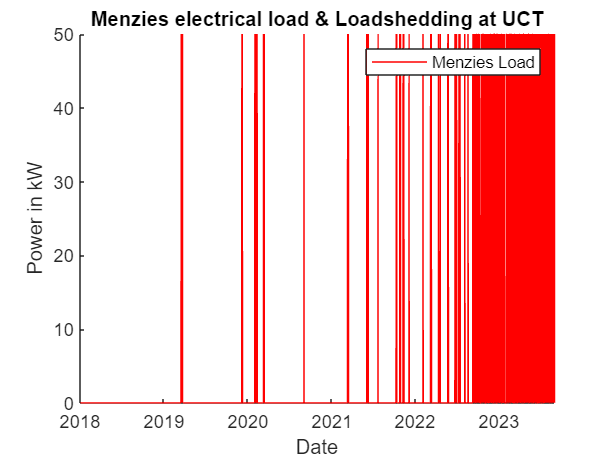

title("Loadshedding at UCT")
xlabel("Date")
ylabel("Power in kW")


writetable(allDateTimes(:,'LoadShedding'), "loadShedding2018_2023.csv");